# Run script multiple times

Define values and run script

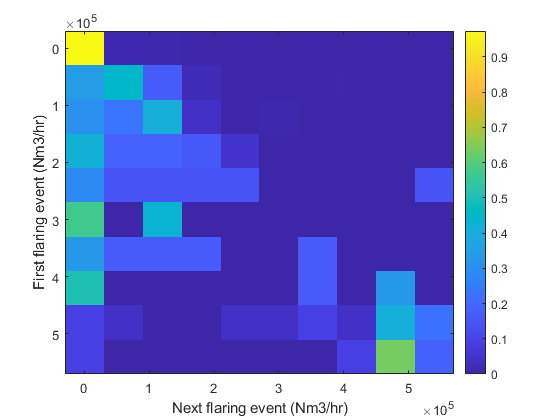

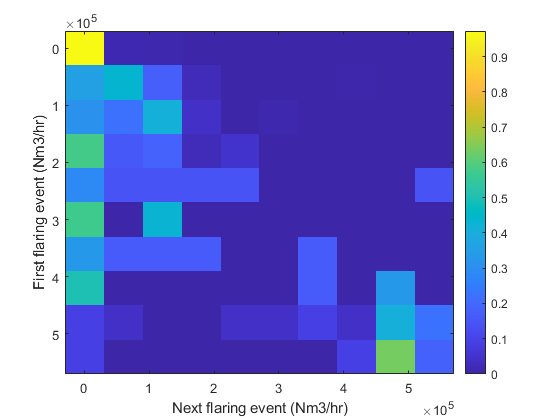

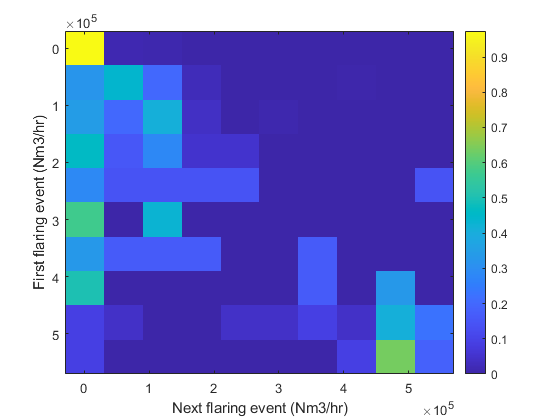

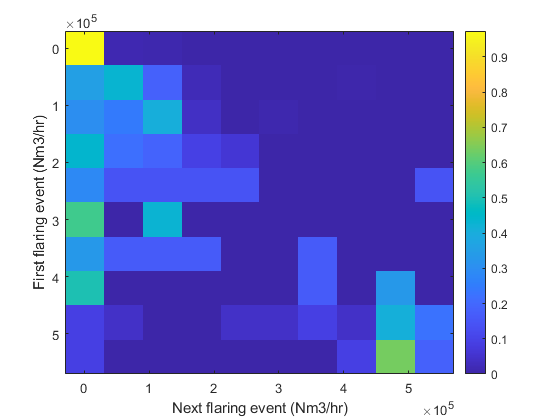

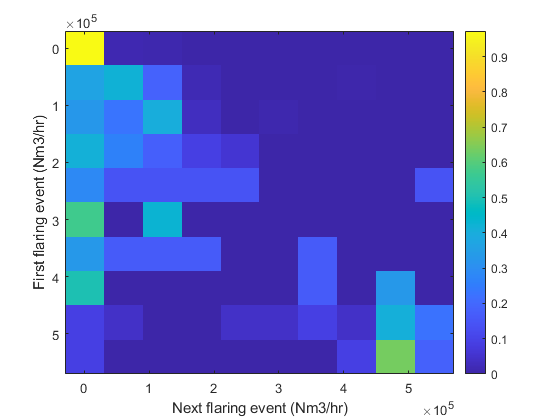

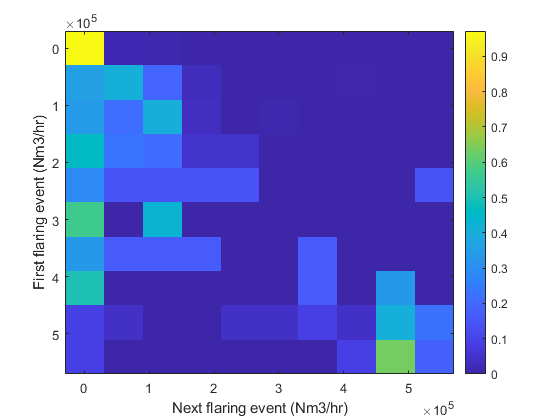

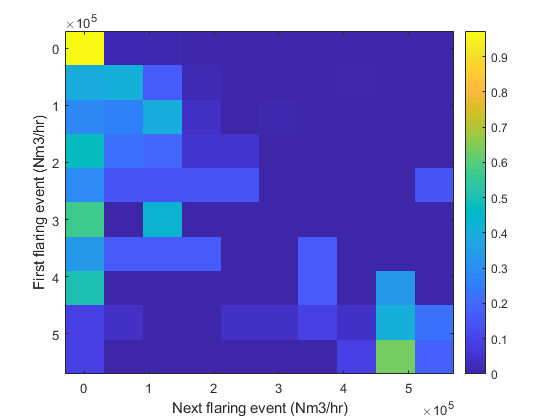

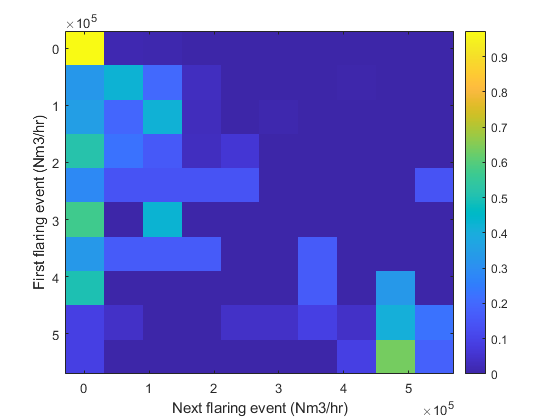

Index in position 1 exceeds array bounds.

Error in markov_matrix (line 20)
    freqMat(fromBinNos(i),nextBinNos(i)) = freqMat(fromBinNos(i),nextBinNos(i)) + 1;

Error in markov_chain (line 60)
    markov_matrix    %get matri

%streams_BFG = [2274.34298, 4548.68596, 6823.02894, 9097.37192, 13646.05788, 18194.74384, 27292.11576, 36389.48768, 45486.8596, 68230.2894, 90973.7192];  % Nm3/hr
capacities_BFG = [25, 50, 75, 100, 150, 200, 300, 400, 500, 750, 1000];  % kt/yr
streams_BFG = 9097.37192;

%streams_BOFG = [3299.284715, 6598.56943, 9897.854145, 13197.13886, 19795.70829, 26394.27772, 39591.41658, 52788.55544];  % Nm3/hr
capacities_BOFG = [25, 50, 75, 100, 150, 200, 300, 400];  % kt/yr
streams_BOFG = 13197.13886;

%streams_COG = [5707.762557, 11415.52511, 17123.28767, 22831.05023, 34246.57534,45662.10046, 57077.62557];  % Nm3/hr
capacities_COG = [25, 50, 75, 100, 150, 200, 250];  % kt/yr
streams_COG = 22831.05023;

prodvolume= [718301.064, 54686.47, 58849.15];    %[Nm3/hr]

%flare_rate_desired = [0.005, 0.0075, 0.01, 0.02, 0.03, 0.04, 0.05];
%FR_model_BFG = [0.005, 0.0075, 0.01, 0.023, 0.029, 0.035, 0.044];
%FR_model_BOFG = [0.003, 0.0065, 0.007, 0.015, 0.025, 0.034, 0.055];
%FR_model_COG = [0.005, 0.0075, 0.03, 0.042];

flare_rate_desired = [0.02];
FR_model_BFG = [0.023];
FR_model_BOFG = [0.015];
FR_model_COG = [0.042];

storage = 1;
storage_sizes = [90000];
op_storage = 0;

countries = [1, 2];

op = 'eur';    % eur or co2

run_model(op, countries, streams_BFG, streams_BOFG, streams_COG, FR_model_BFG, FR_model_BOFG, FR_model_COG, flare_rate_desired, storage, storage_sizes, op_storage)

## Run everything

function[] = run_model(op, countries, streams_BFG, streams_BOFG, streams_COG, FR_model_BFG, FR_model_BOFG, FR_model_COG, flare_rate_desired, storage, storage_sizes, op_storage)
    
    for cc = 1:length(FR_model_BFG)
        
        FR_desired_BFG = flare_rate_desired(cc);
        FR_desired_BOFG = flare_rate_desired(cc);
        
        flare_rate_BFG_in = FR_model_BFG(cc);
        flare_rate_BOFG_in = FR_model_BOFG(cc);
        try
            flare_rate_COG_in = FR_model_COG(cc);
            FR_desired_COG = flare_rate_desired(cc);
        catch
            flare_rate_COG_in = FR_model_COG(3);
            FR_desired_COG = flare_rate_desired(3);
        end
        
        [F, flare_rate_BFG, flare_rate_BOFG, flare_rate_COG] = markov(FR_desired_BFG, flare_rate_BFG_in, FR_desired_BOFG, flare_rate_BOFG_in, FR_desired_COG, flare_rate_COG_in);
        
        for aa = 1:length(streams_BFG)
            
            s1 = streams_BFG(aa);
            try
                s2 = streams_BOFG(aa);
            catch
                s2 = streams_BOFG(1);
            end
            try
                s3 = streams_COG(aa);
            catch
                s3 = streams_COG(1);               
            end
            
            for bb = 1:length(countries)
                
                country = countries(bb);
                    
                if storage == 1
                    
                    if op_storage == 1
                        
                        capacity_BFG = round(aa*365*24*(1.2548157/1000)/1000);
                        capacity_BOFG = round(aa*365*24*(0.865/1000)/1000);
                        capacity_COG = round(aa*365*24*(0.5/1000)/1000);
                        
                        try
                            st1 = optimum_storage_size(aa,cc*100);
                            st2 = optimum_storage_size(aa,cc*100);
                            st3 = optimum_storage_size(aa,cc*100);
                        catch
                            st1 = storage_sizes(dd);
                            st2 = storage_sizes(dd);
                            st3 = storage_sizes(dd);
                            print('Storage size optimation not possible.')
                        end
                        
                        if op == 'eur'
                    
                                Steel_gas_vaule_calculation_model_standalone(country, s1, s2, s3, F, flare_rate_BFG, flare_rate_BOFG, flare_rate_COG, FR_desired_BFG, FR_desired_BOFG, FR_desired_COG, storage, st1, st2, st3)
                                
                        elseif op == 'co2'
                                    
                                Steel_gas_vaule_calculation_model_standalone_CO2(country, s1, s2, s3, F, flare_rate_BFG, flare_rate_BOFG, flare_rate_COG, FR_desired_BFG, FR_desired_BOFG, FR_desired_COG, storage, st1, st2, st3)
                                
                        end
                        
                    elseif op_storage == 0
                
                         for dd = 1:length(storage_sizes)
             
                            st1 = storage_sizes(dd);
                            st2 = storage_sizes(dd);
                            st3 = storage_sizes(dd);
                            
                            if op == 'eur'
                    
                                Steel_gas_vaule_calculation_model_standalone(country, s1, s2, s3, F, flare_rate_BFG, flare_rate_BOFG, flare_rate_COG, FR_desired_BFG, FR_desired_BOFG, FR_desired_COG, storage, st1, st2, st3)
                                
                            elseif op == 'co2'
                                    
                                Steel_gas_vaule_calculation_model_standalone_CO2(country, s1, s2, s3, F, flare_rate_BFG, flare_rate_BOFG, flare_rate_COG, FR_desired_BFG, FR_desired_BOFG, FR_desired_COG, storage, st1, st2, st3)
                                
                            end
        
                         end
                         
                    end
                     
                elseif storage == 0
                    
                    st1 = 0;
                    st2 = 0;
                    st3 = 0;
                                        
                    if op == 'eur'
                
                            Steel_gas_vaule_calculation_model_standalone(country, s1, s2, s3, F, flare_rate_BFG, flare_rate_BOFG, flare_rate_COG, FR_desired_BFG, FR_desired_BOFG, FR_desired_COG, storage, st1, st2, st3)
                            
                    elseif op == 'co2'
                                
                            Steel_gas_vaule_calculation_model_standalone_CO2(country, s1, s2, s3, F, flare_rate_BFG, flare_rate_BOFG, flare_rate_COG, FR_desired_BFG, FR_desired_BOFG, FR_desired_COG, storage, st1, st2, st3)
                            
                    end
                end
            end
        end
    end
end

## Markov chain function

function [F, flare_rate_BFG, flare_rate_BOFG, flare_rate_COG] = markov(FR_desired_BFG, flare_rate_BFG_in, FR_desired_BOFG, flare_rate_BOFG_in, FR_desired_COG, flare_rate_COG_in)
    
    tol = 0.0001;
    
    flare_rate_BFG = 0;
    while flare_rate_BFG < (FR_desired_BFG - tol) || flare_rate_BFG > (FR_desired_BFG + tol)
        [F(:,1), flare_rate_BFG] = markov_chain(flare_rate_BFG_in, 1);
        flare_rate_BFG;
    end
    
    flare_rate_BOFG = 0;
    while flare_rate_BOFG < (FR_desired_BOFG - tol) || flare_rate_BOFG > (FR_desired_BOFG + tol)
        [F(:,2), flare_rate_BOFG] = markov_chain(flare_rate_BOFG_in, 2);
        flare_rate_BOFG;
    end
    
    flare_rate_COG = 0;
    while flare_rate_COG < (FR_desired_COG - tol) || flare_rate_COG > (FR_desired_COG + tol)
        [F(:,3), flare_rate_COG] = markov_chain(flare_rate_COG_in, 3);
        flare_rate_COG;
    end
    
end

## Find optimum storage size

function [op_st_si] = optimum_storage_size(capacity, flare_rate)
    
    filename = 'Results/Plotly graphs/op_st_si_par_cap.csv';
    filename2 = 'Results/Plotly graphs/op_st_si_par_fr.csv';
    filename3 = 'Results/Plotly graphs/optimum_storage_sizes.csv';
    
    cap_par = readmatrix(filename);
    fr_par = readmatrix(filename2);
    op_st_set = readmatrix(filename3);
    
    try
        
        [rowc,colc] = find(op_st_set==capacity);
        [rowf,colf] = find(op_st_set==flare_rate);
        
        op_st_si = op_st_set(rowc,colf);
        
    catch
        
        [rowc,colc] = find(op_st_set==capacity);
        [rowf,colf] = find(op_st_set==flare_rate);

        op_st_si_cap = cap_par(rowc,2) * (capacity^cap_par(rowc,3));
        op_st_si_fr = fr_par(colf,2) * (flare_rate^fr_par(colf,3));
        
        op_st_si = min(op_st_si_cap, op_st_si_fr) +  0.5 * abs(op_st_si_cap - op_st_si_fr);
        
    end

end